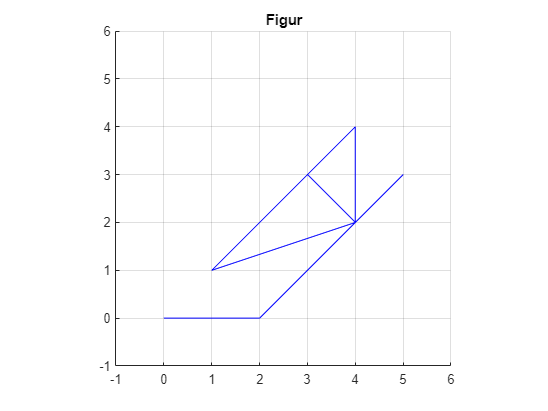

clf
clear
format short
load('MT1A-G9-avbildningar.mat')
origo = [0; 
         0];

hold on
grid on
axis equal
xlim([-1.0 6.0])
ylim([-1.0 6.0])

% X = [0, 1, 2, 3, 4, 5, 4, 3, 4, 4, 1, 3;
%      0, 1, 4, 5, 4, 3, 2, 3, 4, 2, 1, 3];

X = [0, 1, 2, 4, 5, 4, 1, 4, 4, 3;  % icke-symetrisk figur
     0, 0, 0, 2, 3, 2, 1, 4, 2, 3];

xLine = [1; % punkt (1, 0) för att rita linjer
         0];


plot(X(1,:), X(2, :), 'b')
%drawArrow(origo, xLine, 'blue')
title('Figur')

A

A =    -0.5000   -0.8660
   -0.8660    0.5000


B

B =    -0.8660   -0.5000
    0.5000   -0.8660


C

C =     0.9330    0.2500
    0.2500    0.0670


% spegel i linjen y = kx
clf
hold on
grid on
axis equal
xlim([-6.0 6.0])
ylim([-4.0 5.0])
disp('-1, ingen förändring i area, rummets orientering ändras')

-1, ingen förändring i area, rummets orientering ändras


dA = det(A)

dA = -1.0000

[V,D] = eig(A)

V =    -0.8660   -0.5000
   -0.5000    0.8660


D =     -1     0
     0     1



k1 = V(2, 2) / V(2, 1) 

k1 = -1.7321

%k2 = (V(2, 2) - V(2, 1))/V(1, 2) - V(1, 1) % k-värde för speglingslinjen
x = linspace(-8, 8);
y1 = k1*x;
%y2 = k2*x;
Ax = A*X;
AxLine = A*xLine;
V(2, :)

ans =    -0.5000    0.8660


%p2 = [0.424242, -1.27273;
%     -0.791647, 2.37494];

% acosd(A(1,1)) / 2
% asind(A(2,1)) / 2
acosd(V(:,:))

ans =   150.0000  120.0000
  120.0000   30.0000


asind(V(:,:))

ans =   -60.0000  -30.0000
  -30.0000   60.0000


disp('blue to red')

blue to red


cosVradians = dot(V(2, :),xLine)/(norm(V(2, :))*norm(xLine)); % formel för vinkel mellan två vektorer
acosd(cosVradians)

ans = 120.0000

disp('blue to green')

blue to green


cosVradians2 = dot(AxLine,xLine)/(norm(AxLine)*norm(xLine)); % formel för vinkel mellan två vektorer
acosd(cosVradians2)

ans = 120.0000

disp('red to green')

red to green


cosVradians3 = dot(AxLine,V(2, :))/(norm(AxLine)*norm(V(2, :))); % formel för vinkel mellan två vektorer
acosd(cosVradians3)

ans = 120.0000

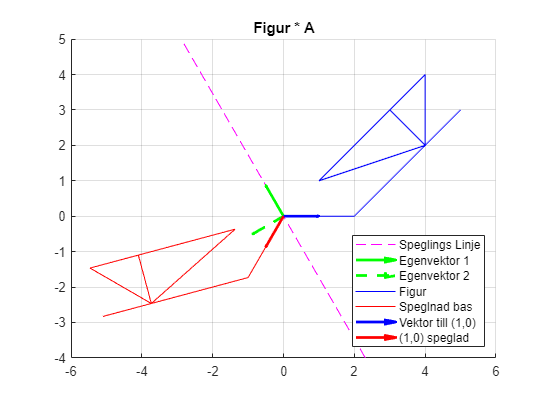


plot(x, y1, 'magenta--')
%plot(x, y2, 'black--')
drawArrow(origo, V(2, :), 'g')
drawArrow(origo, V(1, :), 'g--')
plot(X(1,:), X(2, :), 'b')
plot(Ax(1,:), Ax(2, :), 'r')
drawArrow(origo, xLine, 'b')
drawArrow(origo, AxLine, 'r')

legend('Speglings Linje', 'Egenvektor 1', 'Egenvektor 2', 'Figur', 'Speglnad bas', 'Vektor till (1,0)', '(1,0) speglad', Location='southeast')
title('Figur * A')

% rotationsmatris ca 150 grader
clf
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-3.0 5.0])
B

B =    -0.8660   -0.5000
    0.5000   -0.8660


Bx = B*X;
det(B)

ans = 1

BxLine = B*xLine;
plot(X(1,:), X(2, :), 'b')
plot(Bx(1,:), Bx(2, :), 'r')
drawArrow(origo, xLine, 'b')
drawArrow(origo, BxLine, 'r')

sinDelta = norm(BxLine .* xLine)/(norm(BxLine)*norm(xLine));
asind(sinDelta) + 90

ans = 150.0000


cosVdegrees = dot(BxLine,xLine)/(norm(BxLine)*norm(xLine));
acosd(cosVdegrees)

ans = 150.0000


acosd(B(1,1))

ans = 150.0000

acosd(B(2,2))

ans = 150.0000

acosd(B)

ans =   150.0000  120.0000
   60.0000  150.0000


asind(B)

ans =   -60.0000  -30.0000
   30.0000  -60.0000


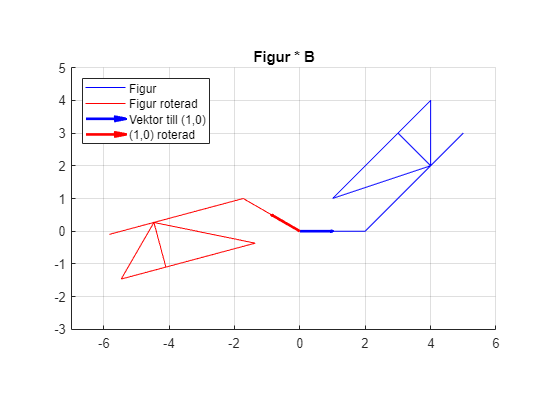


legend('Figur', 'Figur roterad', 'Vektor till (1,0)', '(1,0) roterad',Location='northwest')
title('Figur * B')

% projektion på värderumet längs V(2,:)
clf
hold on
grid on
axis equal
xlim([-2.0 6.0])
ylim([-2.0 6.0])
[V,D] = eig(C)

V =     0.2588   -0.9659
   -0.9659   -0.2588


D =     0.0000         0
         0    1.0000




Cx = C*X;
% CxLine = C*xLine;
plot(X(1,:), X(2, :), 'b')
%drawArrow(origo, CxLine)

%drawArrow(C(1,:), C(2,:))

x1 = linspace(-6, 6);
disp('Projektionslinjens k-värde');

Projektionslinjens k-värde


k1 = V(2,2)/V(2,1)

k1 = 0.2679

y1 = k1*x;
plot(x1, y1, 'g--')
disp('Nolllinjens k-värde')

Nolllinjens k-värde


k2 = V(1,2)/V(1,1)

k2 = -3.7321

y2 = k2*x;
plot(x1, y2, 'c--')

drawArrow(origo, V(1,:), 'black')
drawArrow(origo, V(2,:), 'magenta')

%plot(x, y, 'g--')
disp('Angle of the normal to the projection line')

Angle of the normal to the projection line


asind(V(1,2))

ans = -75.0000

disp('Angle of the projection line')

Angle of the projection line


acosd(2*C(1,1)-1)/2 % cos^2(v) = 1/2*(cos(2v)+1)

ans = 15.0000

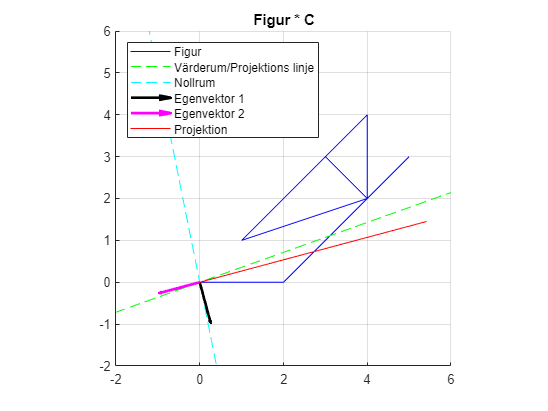

% sin^2(v) = 1/2(1-cos(2v))
% acosd(1-2*C(2,2))/2
plot(Cx(1,:), Cx(2, :), 'red')
legend('Figur', 'Värderum/Projektions linje', 'Nollrum', 'Egenvektor 1', 'Egenvektor 2', 'Projektion', Location='northwest')
title('Figur * C')

% 15 control
clf
hold on
grid on
axis equal
xlim([-2.0 7.0])
ylim([-2.0 7.0])
[V,D] = eig(C)

V =     0.2588   -0.9659
   -0.9659   -0.2588


D =     0.0000         0
         0    1.0000


drawArrow(origo, V(1,:), 'black')
drawArrow(origo, V(2,:), 'magenta')

x = linspace(-6, 6, 12);
k = V(2,2)/V(2,1)

k = 0.2679

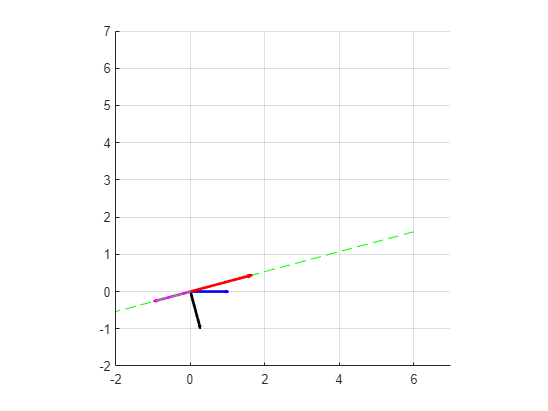

y = k*x;
plot(x, y, 'g--')
proLine = [x(8); y(8)];
drawArrow(origo, xLine, 'b')
drawArrow(origo, proLine, 'r')


cosAngle = dot(proLine,xLine)/(norm(proLine)*norm(xLine));
acosd(cosAngle)

ans = 15.0000

clf
hold on
grid on
axis equal
xlim([-2.0 7.0])
ylim([-2.0 7.0])
L = [1,1;1,1]

L =      1     1
     1     1


det(L)

ans = 0

[V,D] = eig(L)

V =    -0.7071    0.7071
    0.7071    0.7071


D =      0     0
     0     2


drawArrow(origo, V(1,:), 'black')
drawArrow(origo, V(2,:), 'magenta')

Lx = L*X;
% CxLine = C*xLine;
plot(X(1,:), X(2, :), 'b')


x = linspace(-6, 6);
k = V(2,2)/V(2,1)

k = 1

y = k*x;
plot(x, y, 'g--')

asind(V(1,2))

ans = 45.0000


cosAngle = dot(V(2,:),xLine)/(norm(V(2,:))*norm(xLine));
acosd(cosAngle)

ans = 45

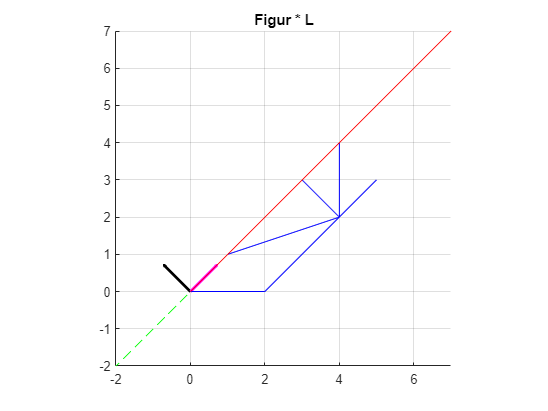


plot(Lx(1,:), Lx(2, :), 'red')

title('Figur * L')

% Illustrera begreppet determinant genom avbildning B.
clf
hold on
grid on
axis equal
xlim([-14.0 7.0])
ylim([-7.0 7.0])
B2 = 2*B

B2 =    -1.7321   -1.0000
    1.0000   -1.7321


acosd(B2)

ans = 	1.0e+02 *

   1.8000 - 0.6567i   1.8000 + 0.0000i
   0.0000 + 0.0000i   1.8000 - 0.6567i


asind(B2)

ans =  -90.0000 +65.6733i -90.0000 + 0.0000i
  90.0000 + 0.0000i -90.0000 +65.6733i


detB2 = det(B2);
detB1 = det(B);
disp('B1 Det:')

B1 Det:


disp('positivt värde ingen förändring i orientering av rummet')

positivt värde ingen förändring i orientering av rummet


sign(detB1)

ans = 1

disp('förändringen i formens area:')

förändringen i formens area:


abs(detB1)

ans = 1

disp('B2 Det:')

B2 Det:


disp('positivt värde ingen förändring i orientering av rummet')

positivt värde ingen förändring i orientering av rummet


sign(detB2)

ans = 1

disp('förändringen i formens area:')

förändringen i formens area:


abs(detB2)

ans = 4

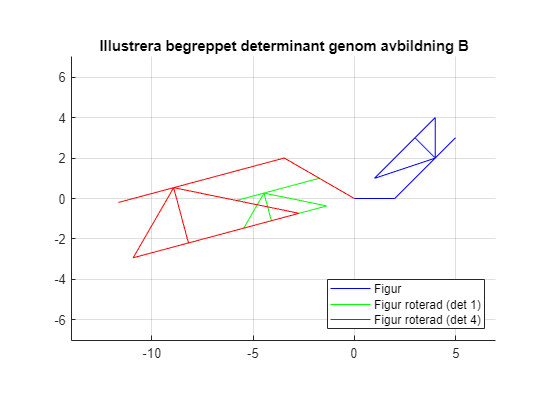

Bx = B*X;
B2x = B2*X;
BxLine = B*xLine;
plot(X(1,:), X(2, :), 'blue')
plot(Bx(1,:), Bx(2, :), 'green')
plot(B2x(1,:), B2x(2, :), 'red')

legend('Figur', 'Figur roterad (det 1)', 'Figur roterad (det 4)', Location='southeast')
title('Illustrera begreppet determinant genom avbildning B')

% Illustrera begreppet invers genom avbildning A. Se Not 1.
% Not 1: Det kan inträffa att den aktuella avbildningen saknar invers. 
%        I så fall skall ni illustrera att avbildningen A saknar invers.
% spegel i linjen y = kx
% visa med x, xline
clf
hold on
grid on
axis equal
xlim([-2.0 2.0])
ylim([-2.0 2.0])
detA = det(A)

detA = -1.0000


A

A =    -0.5000   -0.8660
   -0.8660    0.5000


invA = inv(A)

invA =    -0.5000   -0.8660
   -0.8660    0.5000


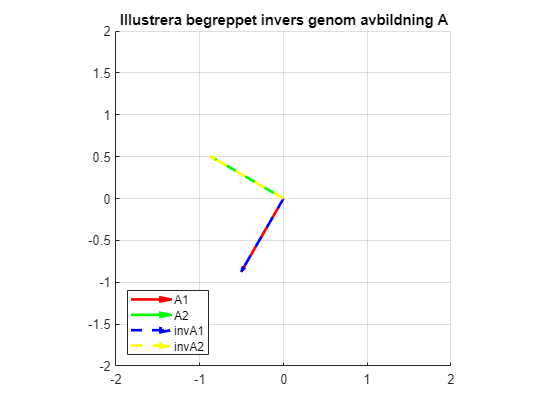


drawArrow(origo, A(1,:), 'red-')
drawArrow(origo, A(2,:), 'green-')

drawArrow(origo, invA(1,:), 'blue--')
drawArrow(origo, invA(2,:), 'yellow--')

legend('A1', 'A2', 'invA1', 'invA2', Location='southwest')
title('Illustrera begreppet invers genom avbildning A')

disp('A is its own inverse (Involutory matrix)')

A is its own inverse (Involutory matrix)


A*A

ans =      1     0
     0     1


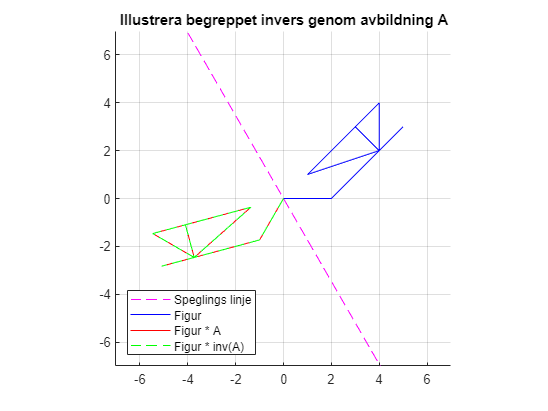


clf
hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])

[V,~] = eig(A);

k = V(2, 2) / V(2, 1); % k-värde för speglingslinjen
x = linspace(-6, 6);
y = k*x;
plot(x, y, 'm--')

AX = A*X;
invAX = A\X;

plot(X(1,:), X(2, :), 'blue')
plot(AX(1,:), AX(2, :), 'r-')
plot(invAX(1,:), invAX(2, :), 'g--')

legend('Speglings linje', 'Figur', 'Figur * A', 'Figur * inv(A)', Location='southwest')
title('Illustrera begreppet invers genom avbildning A')

% Illustrera begreppen egenvärde och egenvektor genom avbildning A.
% fixa
clf
hold on
grid on
axis equal
xlim([-2.0 2.0])
ylim([-2.0 2.0])
det(A)

ans = -1.0000

[eigenvectors,eigenvalues] = eig(A)

eigenvectors =    -0.8660   -0.5000
   -0.5000    0.8660


eigenvalues =     -1     0
     0     1



k = V(2, 2) / V(2, 1);
x = linspace(-6, 6);
y = k*x;

V(1,:) * V(2,:)'

ans = 0


plot(x, y, 'magenta--')
drawArrow(origo, eigenvectors(:,2) * eigenvalues(2,2), 'red')
drawArrow(origo, eigenvectors(:,1) * eigenvalues(1,1), 'green')
sqrt((eigenvectors(1,1) * eigenvalues(1,1))^2 + (eigenvectors(1,2) * eigenvalues(1,1))^2)

ans = 1

sqrt((eigenvectors(2,1) * eigenvalues(2,2))^2 + (eigenvectors(2,2) * eigenvalues(2,2))^2)

ans = 1

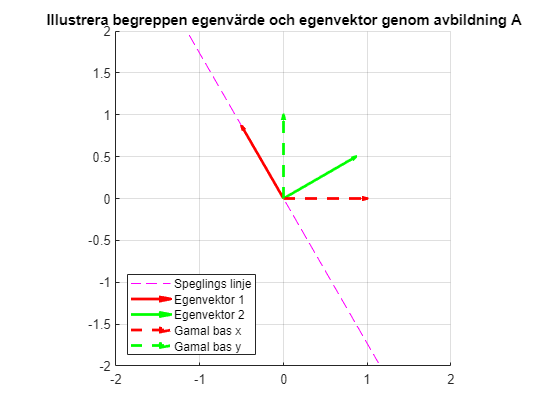

drawArrow(origo, xLine, 'r--')
drawArrow(origo, [0;1], 'g--')

legend('Speglings linje', 'Egenvektor 1', 'Egenvektor 2', 'Gamal bas x', 'Gamal bas y', Location='southwest')
title('Illustrera begreppen egenvärde och egenvektor genom avbildning A')

% Illustrera begreppen nollrum och värderum genom avbildning C.
clf
hold on
grid on
axis equal
xlim([-7.0 7.0])
ylim([-7.0 7.0])

[V,D] = eig(C);
disp('Avrundningsfel, nästan nollrumet')

Avrundningsfel, nästan nollrumet


C * V(1,:)'

ans = 	1.0e+-16 *

         0
   -0.1388


Cx = C*X;
CxLine = C*xLine;

x1 = linspace(-6, 6);
disp('Projektionslinjens k-värde');

Projektionslinjens k-värde


k1 = V(2,2)/V(2,1)

k1 = 0.2679

y1 = k1*x;
plot(x1, y1, '--')
disp('Nolllinjens k-värde')

Nolllinjens k-värde


k2 = V(1,2)/V(1,1)

k2 = -3.7321

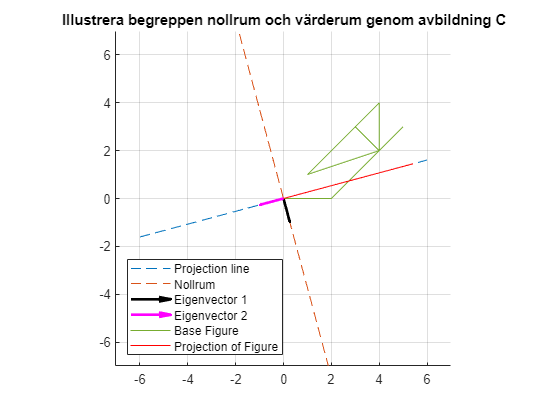

y2 = k2*x;
plot(x1, y2, '--')

drawArrow(origo, V(:,1), 'black')
drawArrow(origo, V(:,2), 'magenta')
plot(X(1,:), X(2, :))
plot(Cx(1,:), Cx(2, :), 'red-')

legend('Projection line', 'Nollrum', 'Eigenvector 1', 'Eigenvector 2', 'Base Figure', 'Projection of Figure', Location='southwest')
title('Illustrera begreppen nollrum och värderum genom avbildning C')

% Illustrera begreppet sammansatt avbildning genom avbildningarna B och A. Se Not 2.
% Not 2: För den sammansatta avbildningen skall ni klargöra i vilken
%        ordning transformationerna verkar på ert objekt och hur
%        motsvarande matrisprodukt ser ut. Ange vilken avbildningsmatris
%        som skall stå till vänster och vilken avbildningsmatris som
%        skall stå till höger.

clf
hold on
grid on
axis equal
xlim([-8.0 8.0])
ylim([-8.0 8.0])

[V,~] = eig(A);
k = V(2, 2) / V(2, 1);
x = linspace(-6, 6);
y = k*x;

plot(x, y, 'yellow-')

A

A =    -0.5000   -0.8660
   -0.8660    0.5000


B

B =    -0.8660   -0.5000
    0.5000   -0.8660


AB = A * B

AB =     0.0000    1.0000
    1.0000   -0.0000


BA = B * A

BA =     0.8660    0.5000
    0.5000   -0.8660


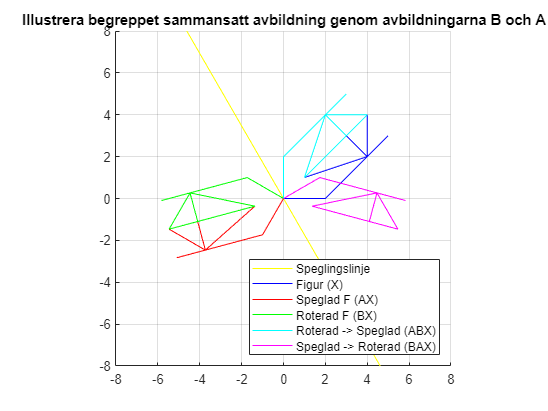

ABX = AB*X;
BAX = BA*X;
AX = A * X;
BX = B * X;
plot(X(1,:), X(2, :), 'blue')
plot(AX(1,:), AX(2, :), 'red')
plot(BX(1,:), BX(2, :), 'green')
plot(ABX(1,:), ABX(2, :), 'cyan')
plot(BAX(1,:), BAX(2, :), 'magenta')
legend('Speglingslinje', 'Figur (X)', 'Speglad F (AX)', 'Roterad F (BX)', 'Roterad -> Speglad (ABX)', 'Speglad -> Roterad (BAX)', Location='southeast')
title('Illustrera begreppet sammansatt avbildning genom avbildningarna B och A')

disp('Förändringsmatrisen längst till vänster agerar först på formen X');

Förändringsmatrisen längst till vänster agerar först på formen X


clf
hold on
grid on
axis equal
xlim([-4.0 4.0])
ylim([-4.0 4.0])

D = [1, 0;
     -1, 1]

D =      1     0
    -1     1


xline = [1;0]

xline =      1
     0


Dxline = D*xline

Dxline =      1
    -1


drawArrow(origo, xline, 'b--')
drawArrow(origo, Dxline, 'r--')
[V,G] = eig(D)

V =          0    0.0000
    1.0000    1.0000


G =      1     0
     0     1


V(:,1)

ans =      0
     1


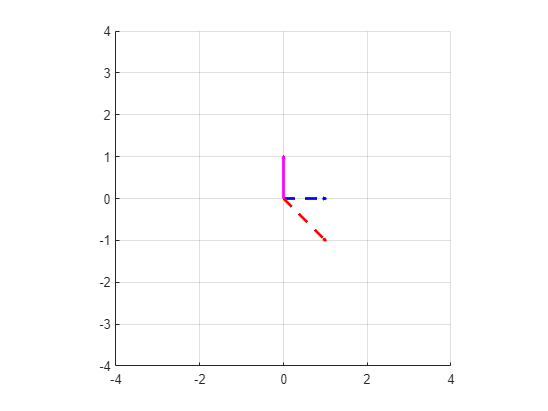

%D*V - G*V

drawArrow(origo, V(:,1), 'b')
drawArrow(origo, V(:,2), 'm')

clf
hold on
grid on
axis equal
xlim([-4.0 4.0])
ylim([-4.0 4.0])

E = [1,1;1,1]

E =      1     1
     1     1


det(E)

ans = 0

xLine

xLine =      1
     0


Ex = E * X

Ex =      0     1     2     6     8     6     2     8     6     6
     0     1     2     6     8     6     2     8     6     6


ExLine = E* xLine

ExLine =      1
     1


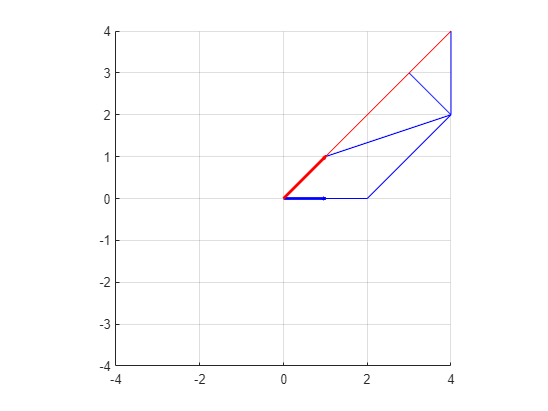

plot(X(1,:), X(2, :), 'b')
plot(Ex(1,:), Ex(2, :), 'r')
drawArrow(origo, xLine, 'b')
drawArrow(origo, ExLine, 'r')


sinDelta = norm(ExLine .* xLine)/(norm(ExLine)*norm(xLine));
asind(sinDelta) + 90

ans = 135


cosVdegrees = max(min(dot(ExLine,xLine)/(norm(ExLine)*norm(xLine)),1),-1);
acosd(cosVradians)

ans = 120.0000


acosd(E(1,1))

ans = 0

acosd(E(2,2))

ans = 0

acosd(E)

ans =      0     0
     0     0


asind(E)

ans =     90    90
    90    90


clf
hold on
grid on
axis equal
xlim([-4.0 4.0])
ylim([-4.0 4.0])
angle = 240;
F = [cosd(angle), -sind(angle);
    sind(angle), cosd(angle)]

F =    -0.5000    0.8660
   -0.8660   -0.5000


F - E

ans =    -1.5000   -0.1340
   -1.8660   -1.5000


det(F)

ans = 1.0000

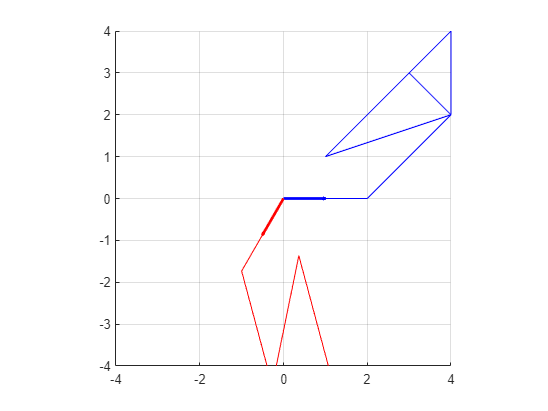

xLine;
Fx = F * X;
FxLine = F* xLine;
plot(X(1,:), X(2, :), 'b')
plot(Fx(1,:), Fx(2, :), 'r')
drawArrow(origo, xLine, 'b')
drawArrow(origo, FxLine, 'r')


sinDelta = norm(FxLine .* xLine)/(norm(FxLine)*norm(xLine));
asind(sinDelta) + 90

ans = 120


cosVdegrees = max(min(dot(FxLine,xLine)/(norm(FxLine)*norm(xLine)),1),-1);
acosd(cosVradians)

ans = 120.0000